## Task 3 (Edge Detection) 

In this task, you will find the edges of an image.

Load the image

clock = im2double(load(fullfile("./","clock.mat")).clock);

Create 3 different kernels, sobel, prewitt, scharr and normalize them

sobel = double(fspecial('sobel'))'./4;
prewitt = double(fspecial('prewitt'))'./3;
a = 3;
b = 10;
scharr = [3.0 10.0 3.0; 0.0 0.0 0.0; -3.0 -10.0 -3.0]'./16;

### filter with sobel

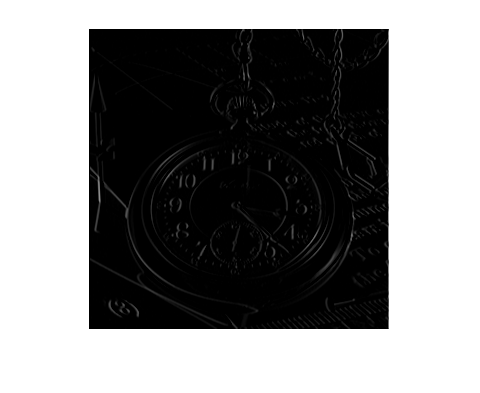

sobel_filtered = imfilter(clock,sobel);
imshow(sobel_filtered)

### filter with prewitt

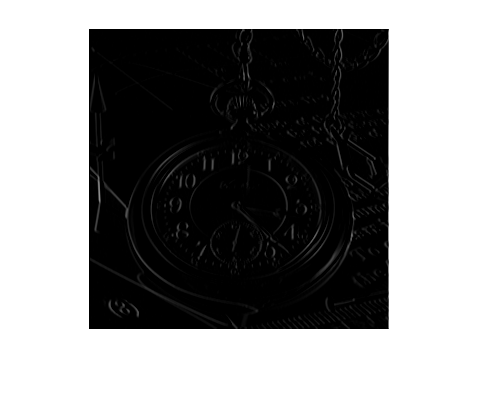

prewitt_filtered = imfilter(clock,prewitt);
imshow(prewitt_filtered)

### filter with scharr

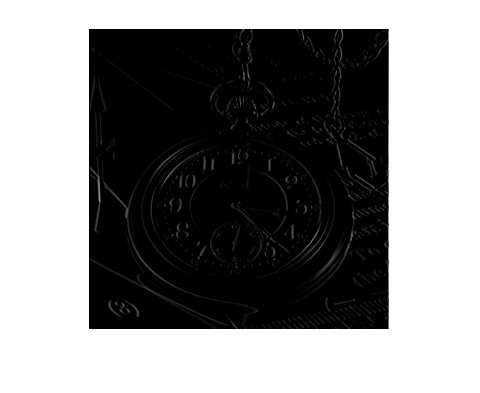

scharr_filtered = imfilter(clock,scharr);
imshow(scharr_filtered)

Notably the sobel filter is best at perserving smaller details such as the text below the clock

### Part 2, threshold

### First I threshold the scharr result

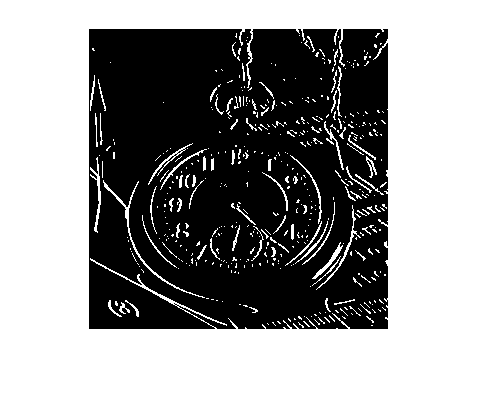

scharr_th = scharr_filtered > (max(scharr_filtered(:)-mean(scharr_filtered(:))))*.1+mean(scharr_filtered(:));
imshow(scharr_th)

### Thresholding the prewitt results

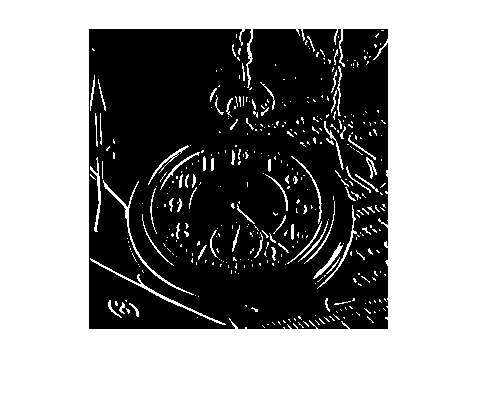

prewitt_th = prewitt_filtered > (max(prewitt_filtered(:)-mean(prewitt_filtered(:))))*.1+mean(prewitt_filtered(:));
imshow(prewitt_th)

### Thresholding the sobel results

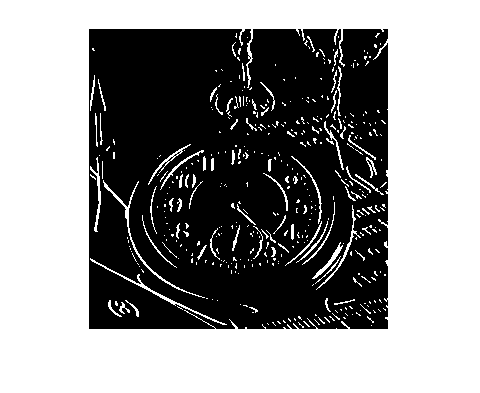

sobel_th = sobel_filtered > (max(sobel_filtered(:)-mean(sobel_filtered(:))))*.1+mean(sobel_filtered(:));
imshow(sobel_th)

Here I used some trial an error to get them to look good, the main take away from this task is that depending on the technique used the threshold will chang a lot. Therefor a relative measure is better than an absolut value. We can also see that all of the edge detectors produce similar results when looking at the thresholded images.